# Project 3: Mechanical Systems

## Overview

Our project evolved out of an interest in Chladni Plates. We quickly realized that modeling particle motion atop a plate oscillating in two dimensions was beyond the scope of the project, involving partial diffierential equations, so we simplified our system down to particle motion atop a one-dimensional oscillator.

This model is based on bouncing a ping pong ball on a ping pong paddle. We are interested in exploring how the ping pong ball will respond to periodic movement of the paddle. 

## Question

What are the resonant input frequencies to a bouncing ping-pong ball? Knowing the resonant frequencies of systems are important to engineering and design of mechanical systems as resonance can lead to increased stress and motion on the resonant components of a system. Furthermore, (insert another example)

Schematic

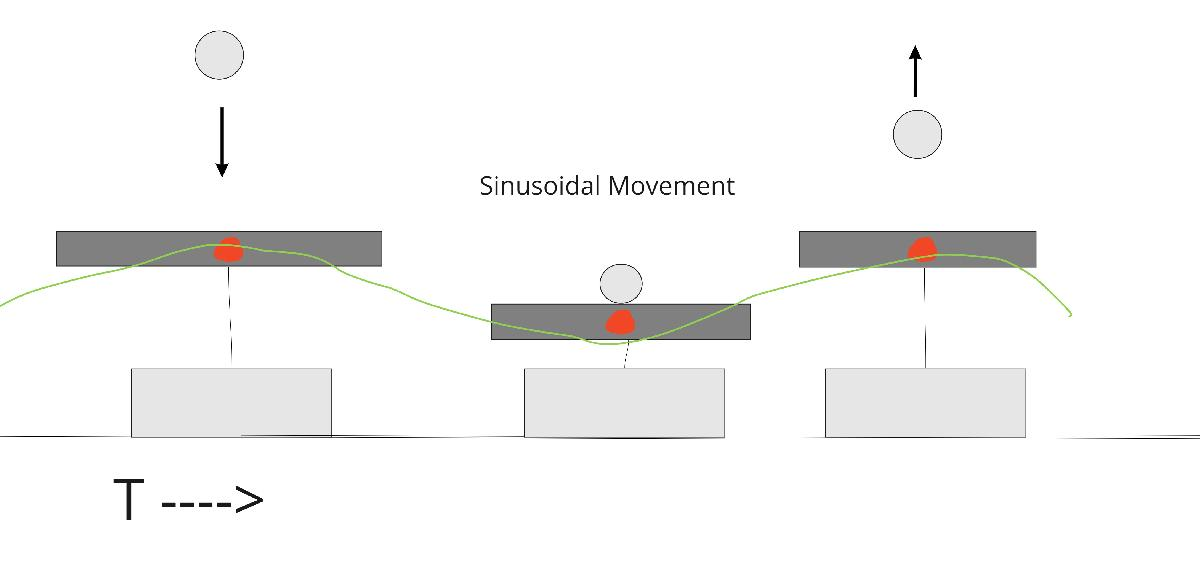

Free Body Diagram

Stock and Flow

We modeled the ping pong ball's motion factoring in both gravity and air resistance.

The equations below define the projectile motion of the ping-pong ball:


$$\begin{array}{l}
v=\textrm{velocity}\\
x=\textrm{position}\\
t=\textrm{time}\\
\\
m=\textrm{mass}\\
g=\textrm{acceleration}\;\textrm{of}\;\textrm{gravity}\;\left(\textrm{negative}\right)\\
r=\textrm{ball}\;\textrm{radius}\\
\rho =\textrm{air}\;\textrm{density}\\
C_d =\textrm{drag}\;\textrm{coefficient}\\
\\
F_{\textrm{air}} =\frac{1}{2}\rho C_d {\textrm{Av}}^2 \\
\textrm{where}\\
A=\pi r^2 \\
\textrm{The}\;\textrm{second}\;\textrm{order}\;\textrm{differential}\;\textrm{equation}\;\textrm{for}\;\textrm{ball}\;\textrm{position}\;\textrm{is}\\
\frac{d^2 x}{{\textrm{dt}}^2 }=F_{\textrm{air}} +g\\
\textrm{Which}\;\textrm{can}\;\textrm{be}\;\textrm{split}\;\textrm{into}\;\textrm{two}\;\textrm{first}\;\textrm{order}\;\textrm{differential}\;\textrm{equations}\\
\frac{\textrm{dv}}{\textrm{dt}}=F_{\textrm{air}} +g\\
\frac{\textrm{dx}}{\textrm{dt}}=v
\end{array}$$


The motion of the plate is defined by


$$\begin{array}{l}
\lambda =\textrm{frequency}\\
a=\textrm{amplitude}\\
\omega =\textrm{angular}\;\textrm{velocity}\\
H=\;\textrm{plate}\;\textrm{height}\\
V=\textrm{plate}\;\textrm{velocity}\\
\textrm{where}\\
\omega =\lambda \left(2\pi \right)\\
\textrm{then}\;\\
H=a\;\sin \left(\omega t\right)\\
V=a\;\omega \;\cos \left(\omega t\right)
\end{array}$$


Collisions between the 

    To abstract the model, we made the following assumptions. First we will be treating the collisions as simple velocity reversals. These velocity direction switches are calculated as the absolute value of the difference between the ball’s and the oscillator’s respective velocities. After being launched off of the surface of the oscillator, the ball will follow simple one-dimensional projectile motion with negative acceleration *g*. In reality, 

## Method

Modeling the ball's motion is quite simple. Between collisions, the ball follows simple projectile motion in one dimension. As no horizontal forces are acting on the ball, it only moves vertically with only the force of gravity acting on it. Further on, other forces will be added to make the ball's motion more true to life, but for the first cut of the model we will stick to gravity alone. Using a predetermined frequency, drop height of the ball, amplitude of the oscillator, and duration of the simulation, we start the oscillator driving with the inputted frequency and amplitude. The ball's dropping motion is modeled with a series of differential equations. When it collides with the driver, a conditional statement flips the velocity and the ball moves upward with velocity equivalent to the difference in velocity between the ball and driver instantly before the collision.

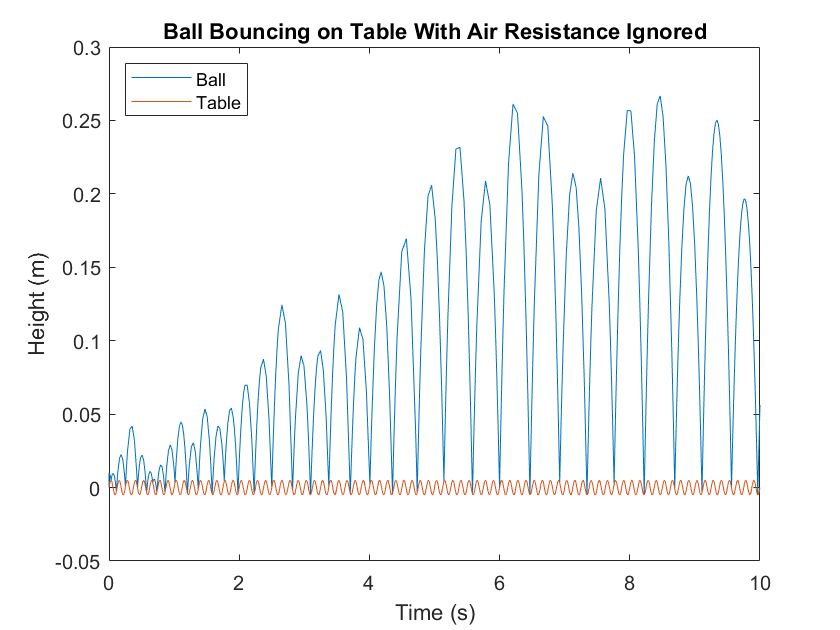

param.freq = 8; %(hz) Enter frequency of oscillator
param.height = 1/100; %(m) Enter starting height of the ball
param.amp = 1/200; %(m) Enter amplitude of oscillator
param.time = 10;    %(s) duration
clf
[T,M] = bouncer_2(param);
plot(T, M(:,1)); %Plots the movement of the ball
hold on
x = linspace(0,10,1000); %Creates a vector with values of regular separation, as contrasted with T, where the step size changes.
plot(x, param.amp * sin(param.freq * 2 * pi * x)); %Plots the movement of the oscillator
xlabel("Time (s)");
ylabel("Height (m)");
legend(["Ball", "Table"], 'Location', 'northwest')
title("Ball Bouncing on Table With Air Resistance Ignored")
hold off

We then incorporated air resistance into our model to better represent our ping pong ball system. To adjust for air resistance, we had to include a mass of the ball, a density of the ball, and its drag coefficient, and its radius. The new function called here, $bouncer\_air\_res()$ takes in these parameters and calculates the drag force given the velocity of the ball at any given point. 

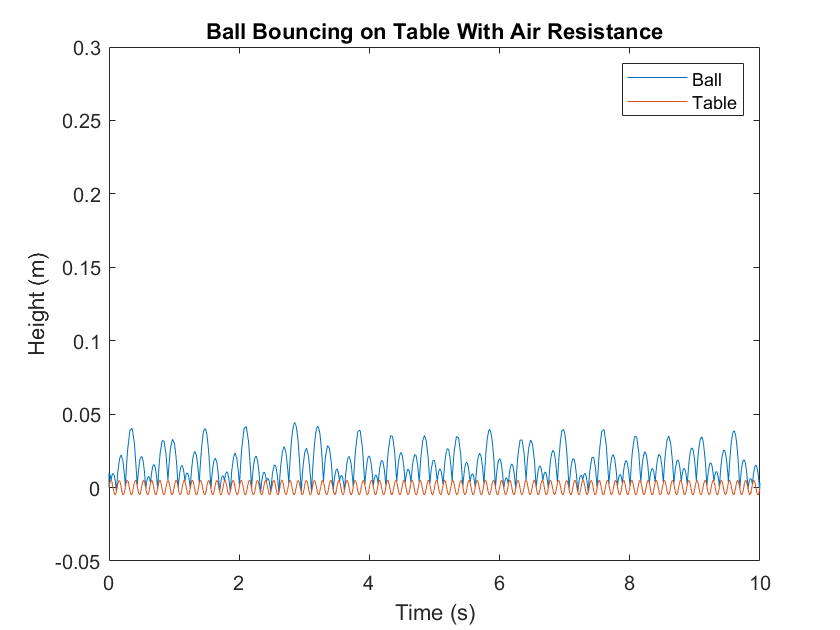

param.freq = 8;             %(hz) Enter frequency of oscillator
param.height = 1/100;       %(m) Enter starting height of the ball
param.amp = 1/200;          %(m) Enter amplitude of oscillator
param.time = 10;            %(s) duration
param.mass = 0.0027;        %kg
param.rho = 1.2;            %kg/m^2
param.c_d = 0.33;         
param.radius = 0.040;       %meters

clf
[T,M] = bouncer_air_res(param);
plot(T, M(:,1));
hold on
x = linspace(0,10,1000);
plot(x, param.amp * sin(param.freq * 2 * pi * x));
xlabel("Time (s)")
ylabel("Height (m)")
legend(["Ball", "Table"])
title("Ball Bouncing on Table With Air Resistance")
ylim([-0.05 0.3])
hold off

## Verification

We can verify this model by running the model with no driven frequency or amplitude. If the ball's motion is periodic between bounces, we will know the model is behaving as expected. Because there is no friction or impact sink for the ball's energy, the ball should bounce uninhibited.

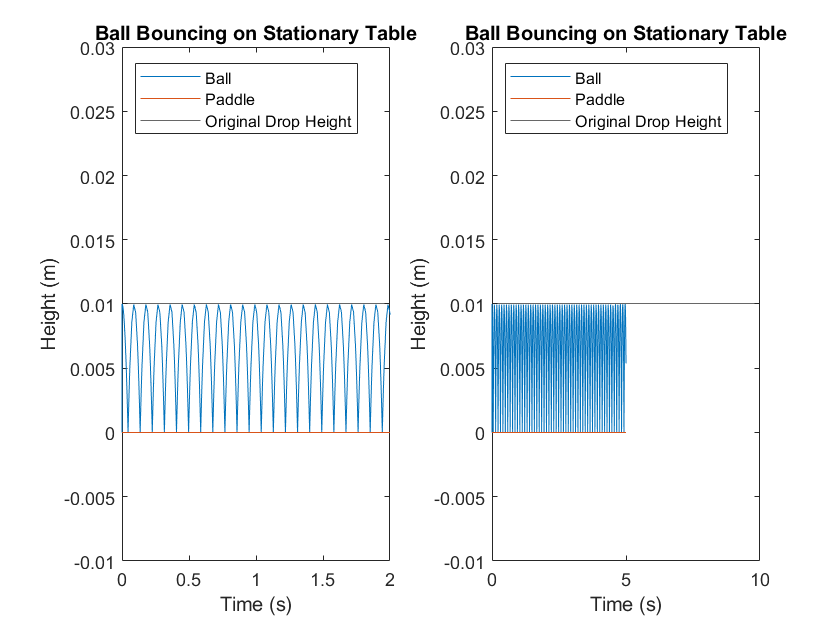

param.height = 1/100;
param.freq = 0;
param.amp = 0;
param.time = 5;

clf
figure;
[T,M] = bouncer_2(param);
subplot(1, 2, 1)
plot(T, M(:,1)); %Plots the movement of the ball
hold on
x = linspace(0,param.time,1000); %Creates a vector with values of regular separation, as contrasted with T, where the step size changes.
plot(x, param.amp * sin(param.freq * 2 * pi * x)); %Plots the movement of the oscillator
yline(param.height);
xlabel("Time (s)");
ylabel("Height (m)");
legend(["Ball", "Paddle", "Original Drop Height"], 'Location', 'northwest')
title("Ball Bouncing on Stationary Table")
ylim([-0.01 0.03])
xlim([0 2])

%{
subplot(1, 2, 2)
plot(T, M(:,1)); %Plots the movement of the ball
hold on
x = linspace(0,param.time,1000); %Creates a vector with values of regular separation, as contrasted with T, where the step size changes.
plot(x, param.amp * sin(param.freq * 2 * pi * x)); %Plots the movement of the oscillator
yline(param.height);
xlabel("Time (s)");
ylabel("Height (m)");
legend(["Ball", "Paddle", "Original Drop Height"], 'Location', 'northwest')
title("Ball Bouncing on Stationary Table")
ylim([-0.01 0.03])
xlim([0 10])

hold off

}%



In order to verify the air resistance is working correctly, we will run the same simulation, with the expectations of watching the amplitude of the ball's bounces slowly decrease through time.

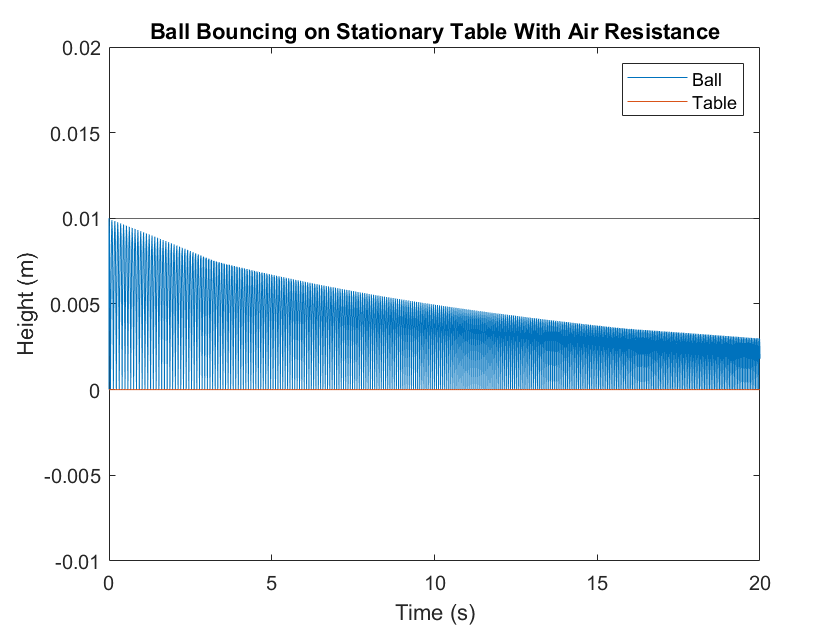

param.freq = 0;             %(hz) Enter frequency of oscillator
param.height = 1/100;       %(m) Enter starting height of the ball
param.amp = 0;              %(m) Enter amplitude of oscillator
param.time = 20;            %(s) duration
param.mass = 0.0027;        %kg
param.rho = 1.2;            %kg/m^2
param.c_d = 0.33;         
param.radius = 0.040;       %meters

clf
[T,M] = bouncer_air_res(param);
plot(T, M(:,1));
hold on
x = linspace(0,param.time,1000);
plot(x, param.amp * sin(param.freq * 2 * pi * x));
yline(param.height)
xlabel("Time (s)")
ylabel("Height (m)")
legend(["Ball", "Table"])
title("Ball Bouncing on Stationary Table With Air Resistance")
ylim([-0.01 0.02])
hold off

The 

Gathering the maximum from the simulation, we are able to sweep frequency to determine which frequencies resonate the most with the ball-bouncing system. 

However, because solely increasing the frequency increases the velocity of the plate and therefore greatly increases the energy the driver transfers to the ball, its also important to decrease the amplitude as the frequency increases. To maintain the same velocity, the amplitude must be inversely proportional to the frequency and directly proportional to some constant $c$ that maintains a ratio between the two. To affect this change, we used the following equation: $Amplitude = c \times \frac{1}{\lambda}$.

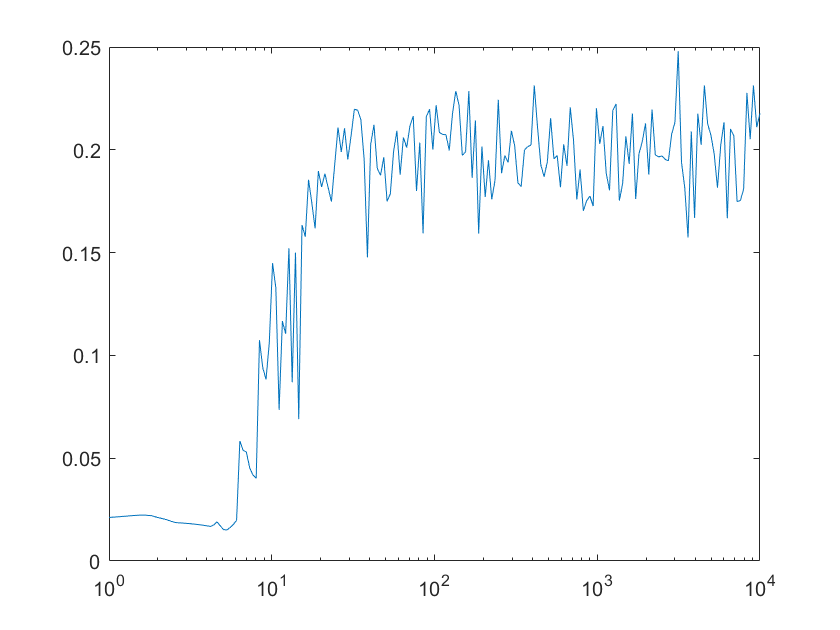

param.height = 1/100;       %(m) Enter starting height of the ball
param.time = 100;           %(s) duration
param.mass = 0.0027;        %kg
param.rho = 1.2;            %kg/m^2
param.c_d = 0.33;         
param.radius = 0.040;       %meters
param.amp = 1/200;          %(m) Amplitude of driver

c = 1/25;   %specifies the ratio between amplitude and the reciprocal of the frequency

n = 200;    %number of plotted points

Maxima = zeros(1,n);        %Initializes the vector of maxima that will be plotted

Frequencies = logspace(0, 4, n);    %Creates a set of n points between 10^0 and 10^4 with a logarithmic scale.

for i = 1:n
    param.freq = Frequencies(i);
    param.amp = c / param.freq;
    [~,M] = bouncer_air_res(param);
    Maxima(i) = max(M(:, 1));
end
clf
plot(Frequencies, Maxima);
set(gca, 'XScale', 'log');

## Interpretation

As expected,

Small changes in frequency have a very radical effect on the maximum height that the ball achieved, meaning that the resonance of the system is fairly precise and somewhat chaotic. In general, the magnitude of frequency also seemed to positively influence the maximum height achieved, meaning that the system tends to resonate with higher frequencies than lower. However, although there was some significant local differences in resonance, they tended to be overshadowed by the influence of the overall magnitude of frequency. Therefore, in a chaotically resonant system like this, resonance is most determined by magnitude of frequency rather than local differences in frequency.

This chaotic behavior makes intuitive sense in context of 

Questions for further:

Is the resolution enough?

Are the bounds the most useful?

Is it actually chaotic?

(Question: Is this ABT effective?, or is it even the conclusion that makes sense?)

(Insert validation)